# Frequency spectra and separation structure functions

We want to have some metrics to quantify the variability in the model.

clear all
close all 

## Frequency spectra

## load obs


obs = load ('../data/traj_cut_DIMES_120days.mat');

% find mean positions of floats
Xm = nanmean(obs.X_pday,1);
Pm = nanmean(obs.Pi_pday,1);

% use velocities recomputed consistently b/w obs and model


## load model

A few depths to form bounds since the obs data is spread out in depth.


d = [2, 5, 7, 12];
for i =1:length(d)
    
    [mod_traj(i).X, mod_traj(i).Y, mod_traj(i).U, mod_traj(i).V, mod_traj(i).T, depth(i)] = loadpairs(d(i));
    
    % get the velocity from forward differencing (will be important for structure functions)
    Unew = nan*mod_traj(i).X;
    Vnew = nan*mod_traj(i).X;
    dt = 1*24*3600; 
    cor = 110*1e3; 
    
    Unew(1:end-1,:) = diff(mod_traj(i).X)*cor.*cosd(mod_traj(i).Y(1:end-1,:))/dt; 
    Vnew(1:end-1,:) = diff(mod_traj(i).Y)*cor/dt; 
    
    mod_traj(i).U = Unew; 
    mod_traj(i).V = Vnew; 
    
    
    mod_traj(i).U(mod_traj(i).U==-999) = NaN;
    mod_traj(i).V(mod_traj(i).V==-999) = NaN;
    mod_traj(i).Y(mod_traj(i).X>360-70) = NaN;
    mod_traj(i).U(mod_traj(i).X>360-70) = NaN;
    mod_traj(i).V(mod_traj(i).X>360-70) = NaN;
    mod_traj(i).X(mod_traj(i).X>360-70) = NaN;
    
    
    
end



## Rotary spec using Jlab

The velocities are estimated using forward differencing, because center differencing smooths. 

% calc complex velocities

X =  obs.X_pday;
nsegs = size(X,2); 
len = size(X,1); 
psi = sleptap(len); 

CV_obs = zeros(len,nsegs);
CV_obs_forward = CV_obs; 


for nseg = 1:nsegs
    CV_obs(:,nseg) = latlon2uv(obs.T_pday(:,nseg), obs.Y_pday(:,nseg), obs.X_pday(:,nseg))/100;
    CV_obs_forward(:,nseg) = latlon2uv(obs.T_pday(:,nseg), obs.Y_pday(:,nseg), obs.X_pday(:,nseg), 'forward')/100;
end

CV_mod = zeros(len, 1200, length(d)); 
CV_mod2 = CV_mod;
CV_mod3 = CV_mod;

for ndep = 1:length(d)
for nseg=1:1200
    CV_mod(:,nseg,ndep) = mod_traj(ndep).U(2:121, nseg) + sqrt(-1)*mod_traj(ndep).V(2:121, nseg);
    CV_mod2(:,nseg,ndep) = latlon2uv(mod_traj(ndep).T(2:121), mod_traj(ndep).Y(2:121,nseg), ...
                        mod_traj(ndep).X(2:121,nseg) )/100;
    CV_mod3(:,nseg,ndep) = latlon2uv(mod_traj(ndep).T(2:121), mod_traj(ndep).Y(2:121,nseg), ...
                        mod_traj(ndep).X(2:121,nseg), 'forward' )/100;
end
end

% Calculate Spectrum

[F_obs, SPP_obs, SNN_obs, SPN_obs] = mspec(CV_obs, psi,'cyclic');
[F_obs_forward, SPP_obs_forward, SNN_obs_forward, SPN_obs_forward] = mspec(CV_obs_forward, psi,'cyclic');

for ndep = 1:length(d)

[F_mod(:,:,ndep), SPP_mod(:,:,ndep), SNN_mod(:,:,ndep), SPN_mod(:,:,ndep)] = mspec(CV_mod(:,:,ndep), psi,'cyclic');
[F_mod2(:,:,ndep), SPP_mod2(:,:,ndep), SNN_mod2(:,:,ndep), SPN_mod2(:,:,ndep)] = mspec(CV_mod2(:,:,ndep), psi,'cyclic');
[F_mod3(:,:,ndep), SPP_mod3(:,:,ndep), SNN_mod3(:,:,ndep), SPN_mod3(:,:,ndep)] = mspec(CV_mod3(:,:,ndep), psi,'cyclic');
end


colors = get(gca, 'ColorOrder'); 

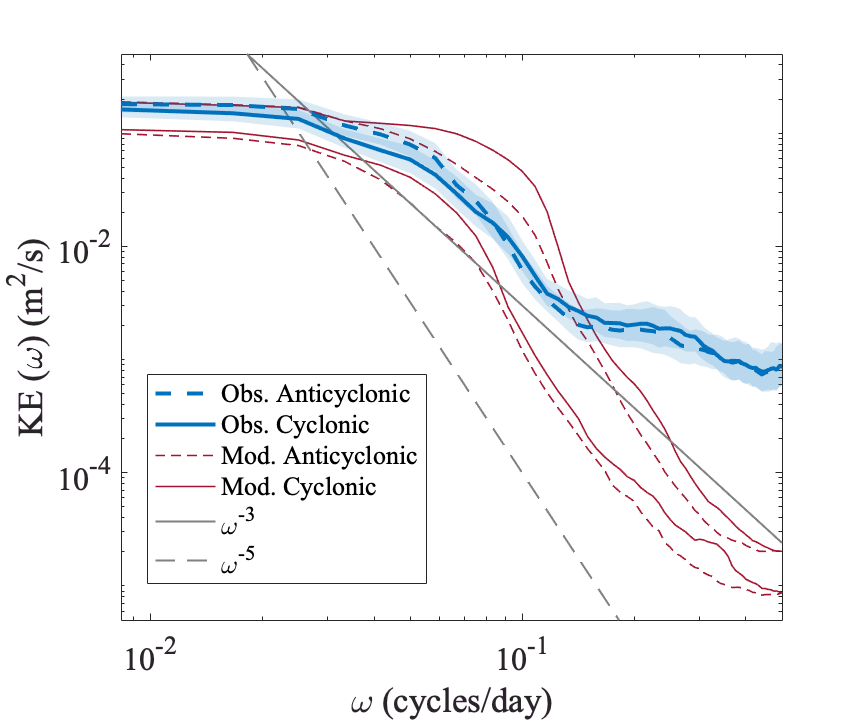


%shallow plot 
figure('unit','inches','pos',[0 0 6. 5.])

id = find(Pm>500 & Pm<1000 & Xm<-80);

[SPP_obs_mean, SPP_obs_ci] = spectra_logerrors(SPP_obs_forward(:, id));
[SNN_obs_mean, SNN_obs_ci] = spectra_logerrors(SNN_obs_forward(:, id));

clear h m t
 


m(1) = loglog(F_mod(:,:,1), nanmean(SPP_mod3(:,:,1),2), '--','linewidth',0.8, 'color', colors(7,:));
hold all

m(2) = loglog(F_mod(:,:,1), nanmean(SNN_mod3(:,:,1),2), '-', 'linewidth',0.8, 'color', colors(7,:));

m(3) = loglog(F_mod(:,:,1), nanmean(SPP_mod3(:,:,2),2), '--','linewidth',0.8, 'color',colors(7,:));
m(4)= loglog(F_mod(:,:,1), nanmean(SNN_mod3(:,:,2),2), '-', 'linewidth',0.8, 'color',colors(7,:));


t(1) = loglog(F_obs, 3e-6*F_obs.^-3, '-', 'color',[0.5 0.5 0.5],'linewidth',1.);
t(2) = loglog(F_obs, 1e-9*F_obs.^-5, '--', 'color',[0.5 0.5 0.5],'linewidth',1.);

h(1) = shadedErrorBar_log(F_obs, SPP_obs_mean, SPP_obs_ci, ...
        {'--','linewidth',2,'color', colors(1,:)}, 1);
h(2) = shadedErrorBar_log(F_obs, SNN_obs_mean, SNN_obs_ci, ...
        {'-','linewidth',2,'color',  colors(1,:)}, 1);

%loglog(f*[1,1] , [0.1,100])
xlim([1/120, 1/2])
%ylim([5e-6, 0.1])
ylim([5e-6, 0.5])

legend([h(1).mainLine, h(2).mainLine, m(1), m(2), t(1), t(2)], ...
    {'Obs. Anticyclonic', 'Obs. Cyclonic', 'Mod. Anticyclonic', ...
    'Mod. Cyclonic', '\omega^{-3}', '\omega^{-5}' },'location','best', 'fontsize',13)
set(gca,'fontsize',16, 'fontname','Times')
xlabel('\omega (cycles/day)')
ylabel('KE (\omega) (m^2/s)')
print('shallow_freq.eps', '-depsc')

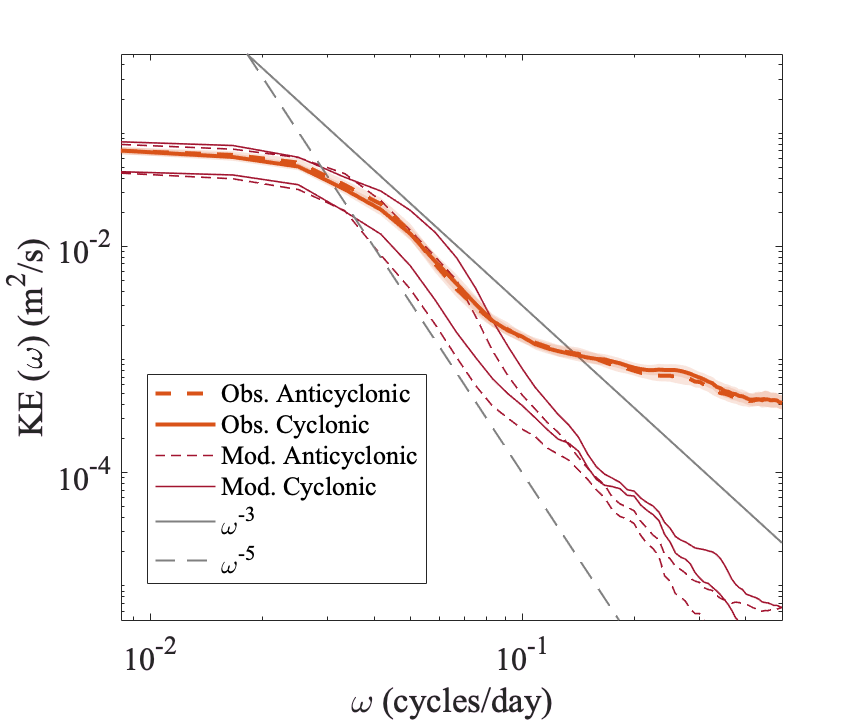

id = find(Pm>1000 & Pm<1800 & Xm<-80);

[SPP_obs_mean, SPP_obs_ci] = spectra_logerrors(SPP_obs_forward(:, id));
[SNN_obs_mean, SNN_obs_ci] = spectra_logerrors(SNN_obs_forward(:, id));

figure('unit','inches','pos',[0 0 6. 5.])

m(1) =loglog(F_mod(:,:,1), nanmean(SPP_mod3(:,:,3),2), '--','linewidth',.8, 'color',colors(7,:));
hold all
m(2) =loglog(F_mod(:,:,1), nanmean(SNN_mod3(:,:,3),2), '-', 'linewidth',.8, 'color',colors(7,:));
loglog(F_mod(:,:,1), nanmean(SPP_mod3(:,:,4),2), '--','linewidth',.8, 'color',colors(7,:));
loglog(F_mod(:,:,1), nanmean(SNN_mod3(:,:,4),2), '-', 'linewidth',.8, 'color',colors(7,:));


t(1) = loglog(F_obs, 3e-6*F_obs.^-3, '-', 'color',[0.5 0.5 0.5],'linewidth',1.0);
t(2) = loglog(F_obs, 1e-9*F_obs.^-5, '--', 'color',[0.5 0.5 0.5],'linewidth',1.);

h(1) = shadedErrorBar_log(F_obs, SPP_obs_mean, SPP_obs_ci, ...
        {'--','linewidth',2,'color', colors(2,:)}, 1);

h(2) = shadedErrorBar_log(F_obs, SNN_obs_mean, SNN_obs_ci, ...
        {'-','linewidth',2,'color', colors(2,:)}, 1);

%loglog(f*[1,1] , [0.1,100])
xlim([1/120, 1/2])
%ylim([5e-6, 0.1])
ylim([5e-6, 0.5])

legend([h(1).mainLine, h(2).mainLine, m(1), m(2), t(1), t(2)], ...
    {'Obs. Anticyclonic', 'Obs. Cyclonic', 'Mod. Anticyclonic', ...
    'Mod. Cyclonic', '\omega^{-3}', '\omega^{-5}' },'location','best', 'fontsize',13)

set(gca,'fontsize',16, 'fontname','Times')
xlabel('\omega (cycles/day)')
ylabel('KE (\omega) (m^2/s)')
print('deep_freq.eps', '-depsc')

## Structure functions 

traj = load ('../data/traj_09_03_13_clean.mat');
% download the full traj data because presence of nans is ok here.,

% delete sections in the Scotia Sea
traj.Uc(traj.Xc>-82) = NaN;
traj.Vc(traj.Xc>-82) = NaN;
traj.Yc(traj.Xc>-82) = NaN;
traj.Xc(traj.Xc>-82) = NaN;

Unew = nan*traj.Xc;
Vnew = nan*traj.Xc;
dt = 1*24*3600; 
cor = 110*1e3; 

Unew(1:end-1,:) = diff(traj.Xc)*cor.*cosd(traj.Yc(1:end-1,:))/dt; 
Vnew(1:end-1,:) = diff(traj.Yc)*cor/dt; 

traj.Uc = Unew; 
traj.Vc = Vnew; 

sep_obs = calculate_seperation_timeseries(traj);

distance_class = [5,50]*1e3;

for i =1:length(d)
    sep_mod(i) = model_sep_calcs(mod_traj(i), distance_class);
end

%% first define the distance axis 
gamma = 1.4;
dist_bin(1) = 1000; % in m
dist_bin = gamma.^(0:100)*dist_bin(1);
id = find(dist_bin>800*10^3,1);
dist_bin = dist_bin(1:id);
dist_bin(2:end+1) = dist_bin(1:end);
dist_bin(1) = 0;
dist_axis = 0.5*(dist_bin(1:end-1) + dist_bin(2:end));

%%
diff_pres = 100; 
plevel = [500 1000 1800];

% obs
[S2ll_obs_deep_mean, S2ll_obs_deep_ci] = S2ll(sep_obs, dist_bin, diff_pres, plevel(2:3)); 
[S2ll_obs_shallow_mean, S2ll_obs_shallow_ci] = S2ll(sep_obs, dist_bin, diff_pres, plevel(1:2)); 

% model
for i = 1:length(d)
    S2ll_mod(:, i)  = S2ll_model(sep_mod(i).sep, dist_bin); 
end

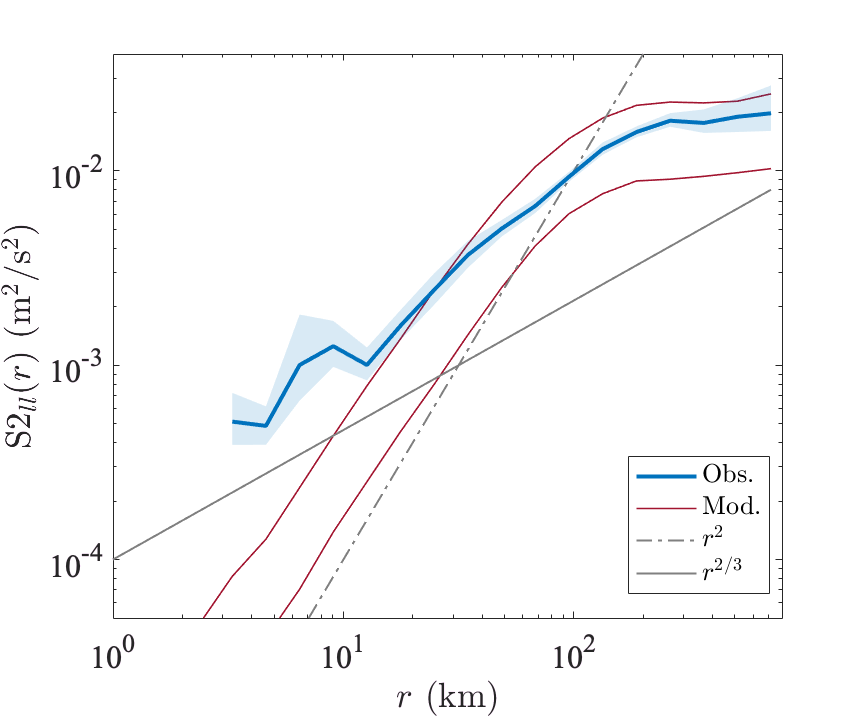

% shallow figure
clear h g 
%figure('rend','painters','pos',[10 10 800 600])
figure('unit','inches','pos',[0 0 6 5])

%h(2) = shadedErrorBar_log(dist_axis/1e3, S2ll_obs_shallow_mean, S2ll_obs_shallow_ci, ...
%            {'-','linewidth',3,'color', colors(2,:)}, 1);
        
g(1) = loglog(dist_axis/1e3, S2ll_mod(:,1), '-', 'linewidth',0.8,'color',colors(7,:));
hold all 
g(2) = loglog(dist_axis/1e3, S2ll_mod(:,2), '-', 'linewidth',0.8,'color', colors(7,:));
%r0 = loglog(dist_axis/1e3, dist_axis./dist_axis*0.1, '-','color', [0.5 0.5 0.5], 'linewidth',1);  
%r23 = loglog(dist_axis/1e3, 100*dist_axis.^(-2/3), '--', 'color', [0.5 0.5 0.5], 'linewidth',1); 
%r2 = loglog(dist_axis/1e3, 1e8*dist_axis.^(-2), '-.', 'color', [0.5 0.5 0.5], 'linewidth',1); 
r23 = loglog(dist_axis/1e3, 1e-6*dist_axis.^(2/3), '-','color', [0.5 0.5 0.5], 'linewidth',1.);
%r1 =loglog(dist_axis/1e3, 10^(-7.5)*dist_axis.^(1), '--','color', [0.5 0.5 0.5], 'linewidth',1.5);
r2 =loglog(dist_axis/1e3, 1e-12*dist_axis.^(2), '-.','color', [0.5 0.5 0.5], 'linewidth',1.);

h(1) = shadedErrorBar_log(dist_axis/1e3, S2ll_obs_shallow_mean, S2ll_obs_shallow_ci, ...
            {'-','linewidth',2,'color', colors(1,:)}, 1);

        
A = legend([h(1).mainLine,  g(1), r2, r23], ...
    {'Obs.', 'Mod.',  '$r^{2}$', '$r^{2/3}$'} ...
    , 'Interpreter','Latex', 'fontsize',13);
%legend boxoff
set(A, 'location','best') 
set(gca, 'fontsize', 16, 'fontname', 'times') 

axis([1 800 5e-5 4e-2])

xlabel('$r$ (km)', 'Interpreter', 'Latex') 
ylabel('S2$_{ll} (r)$ (m$^{2}$/s$^{2}$)', 'Interpreter','Latex')

print('sf_shallow.eps', '-depsc')

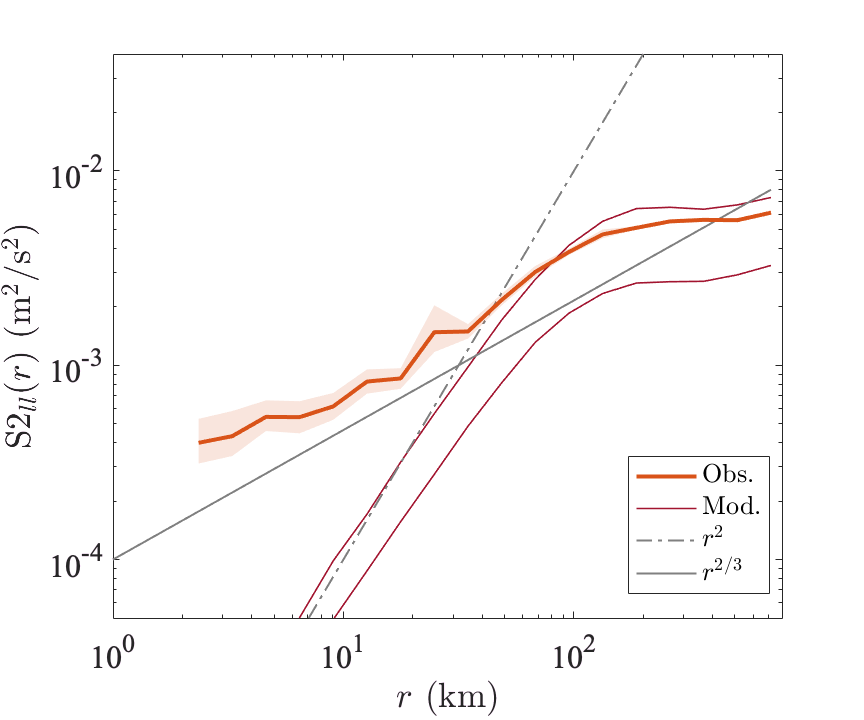

% deep figure
clear h g 
figure('unit','inches','pos',[0. 0. 6 5])

g(1) = loglog(dist_axis/1e3, S2ll_mod(:,3), '-', 'linewidth',.8,'color',colors(7,:));
hold all
g(2) = loglog(dist_axis/1e3, S2ll_mod(:,4), '-', 'linewidth',.8,'color', colors(7,:));
% loglog(dist_axis/1e3, S2ll_mod_noise, '-', 'linewidth',1,'color', colors(7,:));
%r0 = loglog(dist_axis/1e3, dist_axis./dist_axis*0.1, '-','color', [0.5 0.5 0.5], 'linewidth',1);  
%r23 = loglog(dist_axis/1e3, 100*dist_axis.^(-2/3), '--', 'color', [0.5 0.5 0.5], 'linewidth',1); 
%r2 = loglog(dist_axis/1e3, 1e8*dist_axis.^(-2), '-.', 'color', [0.5 0.5 0.5], 'linewidth',1); 
r23 = loglog(dist_axis/1e3, 1e-6*dist_axis.^(2/3), '-','color', [0.5 0.5 0.5], 'linewidth',1.);
% r1 =loglog(dist_axis/1e3, 10^(-7.5)*dist_axis.^(1), '--','color', [0.5 0.5 0.5], 'linewidth',1.5);
r2 =loglog(dist_axis/1e3, 1e-12*dist_axis.^(2), '-.','color', [0.5 0.5 0.5], 'linewidth',1.);

h(1) = shadedErrorBar_log(dist_axis/1e3, S2ll_obs_deep_mean, S2ll_obs_deep_ci, ...
            {'-','linewidth',2,'color', colors(2,:)}, 1);

A = legend([h(1).mainLine,  g(1), r2,  r23], ...
    {'Obs.', 'Mod.',  '$r^{2}$', '$r^{2/3}$'} ...
    , 'Interpreter','Latex', 'fontsize',13);
%legend boxoff
set(A, 'location','best') 
set(gca, 'fontsize', 16, 'fontname', 'times') 

axis([1 800 5e-5 4e-2])

xlabel('$r$ (km)', 'Interpreter', 'Latex') 
ylabel('S2$_{ll} (r)$ (m$^{2}$/s$^{2}$)', 'Interpreter','Latex')

print('sf_deep.eps', '-depsc')

## Adding noise and its impact on the spectra

% add some noise to some model output
Lk = 2; 

xrand = Lk*randn(736, 1200);
yrand = Lk*randn(736, 1200);


[Ylrand, Xlrand] = xy2latlon(xrand, yrand, -55, 270); 
Xlrand = Xlrand+360; 

%mod_traj_noise.X = mod_traj(3).X + xrand*Lk.*cosd(mod_traj(3).Y);
%mod_traj_noise.Y = mod_traj(3).Y + yrand*Lk;
mod_traj_noise.X = mod_traj(3).X + Xlrand - Xlrand(1,:);
mod_traj_noise.Y = mod_traj(3).Y + Ylrand - Ylrand(1,:);

mod_traj_noise.T = mod_traj(3).T;

% spectra with noise 
CV_noise = zeros(len, 1200);
CV_mod_noise = zeros(len, 1200);

for nseg=1:1200
    CV_noise(:,nseg) = latlon2uv(mod_traj_noise.T(2:121), Ylrand(2:121,nseg), ...
                        Xlrand(2:121,nseg), 'forward' )/100;
    CV_mod_noise(:,nseg) = latlon2uv(mod_traj_noise.T(2:121), mod_traj_noise.Y(2:121,nseg), ...
                        mod_traj_noise.X(2:121,nseg), 'forward' )/100;
end

[F_mod_noise, SPP_mod_noise, SNN_mod_noise, SPN_mod_noise] = mspec(CV_mod_noise, psi,'cyclic');
[F_noise, SPP_noise, SNN_noise, SPN_noise] = mspec(CV_noise, psi,'cyclic');

% structure function with noise
Unew = nan*mod_traj_noise.X;
Vnew = nan*mod_traj_noise.X;
dt = 1*24*3600; 
cor = 110*1e3; 

Unew(1:end-1,:) = diff(mod_traj_noise.X)*cor.*cosd(mod_traj_noise.Y(1:end-1,:))/dt; 
Vnew(1:end-1,:) = diff(mod_traj_noise.Y)*cor/dt; 

mod_traj_noise.U = Unew; 
mod_traj_noise.V = Vnew; 
    
sep_mod_noise = model_sep_calcs(mod_traj_noise, distance_class);

S2ll_mod_noise  = S2ll_model(sep_mod_noise.sep, dist_bin); 


% Plot frequency spec with noise 
id = find(Pm>1000 & Pm<1800 & Xm<-80);

[SPP_obs_mean, SPP_obs_ci] = spectra_logerrors(SPP_obs_forward(:, id));
[SNN_obs_mean, SNN_obs_ci] = spectra_logerrors(SNN_obs_forward(:, id));

figure 
h(1) = shadedErrorBar_log(F_obs, SPP_obs_mean, SPP_obs_ci, ...
        {'--','linewidth',2,'color', colors(2,:)}, 1);
    %loglog(F_obs, mean(SPP_obs(:, id),2),'--', 'linewidth',2,'color', [0.3010    0.7450    0.9330])
hold all
%loglog(F_obs, mean(SNN_obs(:, id),2), '-', 'linewidth',2,'color', [0.3010    0.7450    0.9330])
h(2) = shadedErrorBar_log(F_obs, SNN_obs_mean, SNN_obs_ci, ...
        {'-','linewidth',2,'color', colors(2,:)}, 1);
%loglog(F_mod, nanmean(SPP_mod,2), 'linewidth',1, 'color',[0.8500    0.3250    0.0980])
%loglog(F_mod, nanmean(SNN_mod,2), '--', 'linewidth',1, 'color',[0.8500    0.3250    0.0980])

%loglog(F_mod, nanmean(SPP_mod2,2), '--','linewidth',2, 'color',[0.8500    0.3250    0.0980])
m(1) =loglog(F_mod_noise, nanmean(SPP_mod_noise,2), '--','linewidth',1, 'color',colors(7,:));
m(2) =loglog(F_mod_noise, nanmean(SNN_mod_noise,2), '-', 'linewidth',1, 'color',colors(7,:));

m(1) =loglog(F_mod_noise, nanmean(SPP_noise,2), '--','linewidth',1, 'color',colors(7,:));
m(2) =loglog(F_mod_noise, nanmean(SNN_noise,2), '-', 'linewidth',1, 'color',colors(7,:));


xlim([1/120, 1/2])
ylim([5e-6, 0.5])

% deep figure
clear h g 
%figure('rend','painters','pos',[10 10 800 600])
figure

h(1) = shadedErrorBar_log(dist_axis/1e3, S2ll_obs_deep_mean, S2ll_obs_deep_ci, ...
            {'-','linewidth',2,'color', colors(2,:)}, 1);
hold all
%h(2) = shadedErrorBar_log(dist_axis/1e3, S2ll_obs_shallow_mean, S2ll_obs_shallow_ci, ...
%            {'-','linewidth',3,'color', colors(2,:)}, 1);
        
g(1) = loglog(dist_axis/1e3, S2ll_mod(:,3), '-', 'linewidth',1,'color',colors(7,:));
g(2) = loglog(dist_axis/1e3, S2ll_mod(:,4), '-', 'linewidth',1,'color', colors(7,:));
loglog(dist_axis/1e3, S2ll_mod_noise, '-', 'linewidth',1,'color', colors(7,:));
%r0 = loglog(dist_axis/1e3, dist_axis./dist_axis*0.1, '-','color', [0.5 0.5 0.5], 'linewidth',1);  
%r23 = loglog(dist_axis/1e3, 100*dist_axis.^(-2/3), '--', 'color', [0.5 0.5 0.5], 'linewidth',1); 
%r2 = loglog(dist_axis/1e3, 1e8*dist_axis.^(-2), '-.', 'color', [0.5 0.5 0.5], 'linewidth',1); 
r23 = loglog(dist_axis/1e3, 1e-6*dist_axis.^(2/3), '-','color', [0.5 0.5 0.5], 'linewidth',1.5);
r1 =loglog(dist_axis/1e3, 10^(-7.5)*dist_axis.^(1), '--','color', [0.5 0.5 0.5], 'linewidth',1.5);
r2 =loglog(dist_axis/1e3, 1e-12*dist_axis.^(2), '-.','color', [0.5 0.5 0.5], 'linewidth',1.5);

A = legend([h(1).mainLine,  g(1), r2, r1, r23], ...
    {'Obs.', 'Mod.',  '$r^{2}$', '$r^{1}$', '$r^{2/3}$'} ...
    , 'Interpreter','Latex');
%legend boxoff
set(A, 'location','best') 
set(gca, 'fontsize', 16, 'fontname', 'times') 

axis([1 800 1e-5 4e-2])

xlabel('$r$ (km)', 'Interpreter', 'Latex') 
ylabel('S2$_{ll} (r)$ (m$^{2}$/s$^{2}$)', 'Interpreter','Latex')